# Homework 3: Fourier, Sobel, Transformations, and Registration

#### Name: Grant Roberts

#### Due: 03/24/2020

#### BMI/CS 567: Medical Image Analysis 

## **3.1     Fourier & Sobel**

**In the first section of this homework you will learn about the Sobel filter and investigate some Fourier transform properties. In this section you may use Matlab built-in functions.**

**(a) The Sobel filter approximates the gradient of an image using a pair of 3 x 3 kernel filters:**


$${\mathrm{K}}_x \;\;=\;\left\lbrack \begin{array}{ccc}
-1 & 0 & 1\\
-2 & 0 & 2\\
-1 & 0 & 1
\end{array}\right\rbrack ,\;\;\;\;\;\;\;\;\;\;\;\;{\mathrm{K}}_y =\left\lbrack \begin{array}{ccc}
1 & 2 & 1\\
0 & 0 & 0\\
-1 & -2 & -1
\end{array}\right\rbrack$$


${\mathrm{K}}_x$** estimates the gradient in the horizontal direction, and **${\mathrm{K}}_y$** estimates the gradient in the vertical direction. The magnitude of the overall gradient is the sum of both. This is a very popular edge detection filter. Load the **`liver.jpeg`** image from the course website. Use **`subplot`** to display:**

- **The original image **$\mathrm{X}$

x = imread('liver.jpeg');
x = [zeros(107,339);x;zeros(110,339)]; % square image
x = [zeros(512,85),x,zeros(512,88)]; % turn into zero-padded 512x512 image
figure; subplot(2,2,1); imshow(x,[]); title('Zero Padded Image')

- **The result of convolving **$\mathrm{X}$** with **${\mathrm{K}}_x$**, i.e., **${\mathrm{X}*\mathrm{K}}_x$

kx = [-1 0 1; -2 0 2; -1 0 1]; % Sobel filter in x
x_kx = conv2(kx,x);
subplot(2,2,2); imshow(x_kx,[]); title('Image Convolved with kx');

- **The result of convolving **$\mathrm{X}$** with **${\mathrm{K}}_y$**, i.e., **${\mathrm{X}*\mathrm{K}}_y$

ky = [1 2 1;0 0 0;-1 -2 -1]; % Sobel filter in y
x_ky = conv2(ky,x);
subplot(2,2,3); imshow(x_ky,[]), title('Image Convolved with ky');

- **The sum of both convolutions, i.e., **${\mathrm{X}*\mathrm{K}}_x$** + **${\mathrm{X}*\mathrm{K}}_y$**.**

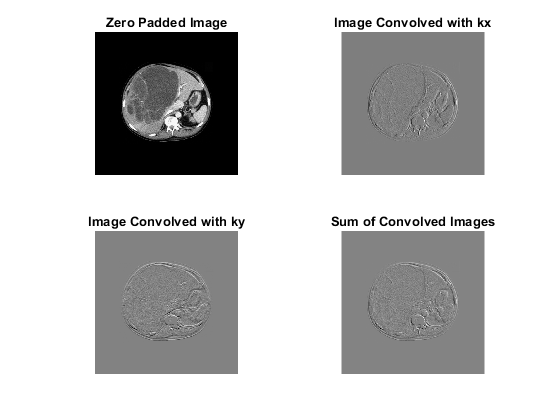

x_sum = x_kx + x_ky; % Sum of Sobel filtered images
subplot(2,2,4); imshow(x_sum,[]); title('Sum of Convolved Images');

**(b)  Use **`subplot`** to display the original Image **$\mathrm{X}$ **and its Fourier transform, with lower frequencies at the center, and properly log-scaled.**

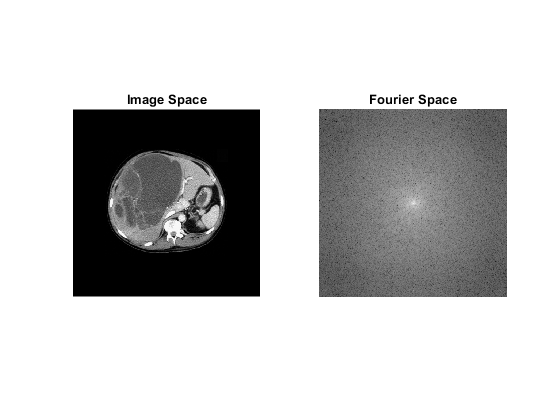

X = fft2c(x);
figure; subplot(1,2,1); imshow(x,[]); title('Image Space')
subplot(1,2,2); imshow(log(abs(X)),[]); title('Fourier Space')

**(c) We will now study the effect of convolution in the Fourier domain. Letting **$\hat{\mathrm{X}}$**, **${\hat{\mathrm{K}} }_x$**, **${\hat{\mathrm{K}} }_y$** be the Fourier transforms of **$\hat{\mathrm{X}}$**, **${\mathrm{K}}_x$**, **${\mathrm{K}}_y$** (properly padded with zeros), compute and display (using **`subplot`**):**

- 
$$\hat{\mathrm{X}} \odot {\hat{\mathrm{K}} }_x$$


kx_pad = padarray(kx,[1 1],'pre'); % Add an extra row
kx_pad = padarray(kx_pad,[254 254]); % Pad with zeros to match size of X
KX = fft2c(kx_pad);
X_KX = X.*KX;
figure; subplot(1,3,1); imshow(X_KX,[]); title('Kx Filter - Fourier')

- 
$$\hat{\mathrm{X}} \odot {\hat{\mathrm{K}} }_y$$


ky_pad = padarray(ky,[1 1],'pre');
ky_pad = padarray(ky_pad,[254 254]);
KY = fft2c(ky_pad);
X_KY = X.*KY;
subplot(1,3,2); imshow(X_KY,[]); title('Ky Filter - Fourier')

- $\hat{\mathrm{X}} \odot {\hat{\mathrm{K}} }_x$ + $\hat{\mathrm{X}} \odot {\hat{\mathrm{K}} }_y$

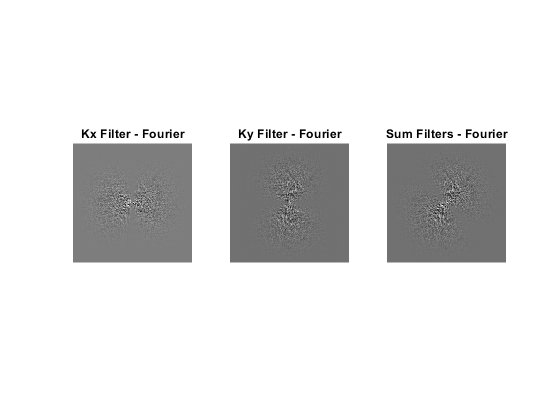

X_SUM = X_KX + X_KY;
subplot(1,3,3); imshow(X_SUM,[]); title('Sum Filters - Fourier')

**Is there some pattern that you can recognize? E.g., do **${\mathrm{K}}_x$** and **${\mathrm{K}}_y$** behave like low-pass or high-pass filters?**

Multiplying by Kx in the Fourier Domain has a very similar appearance to convolving kx with the image in image space. Particularly, it looks like k-space appears to be 'edge filtered' in the respective directions of the filters. 

**(d) Compute and display (using **`subplot`**) the inverse Fourier transform of the matrices in (c). How do these compare with the direct convolutions from (a)?**

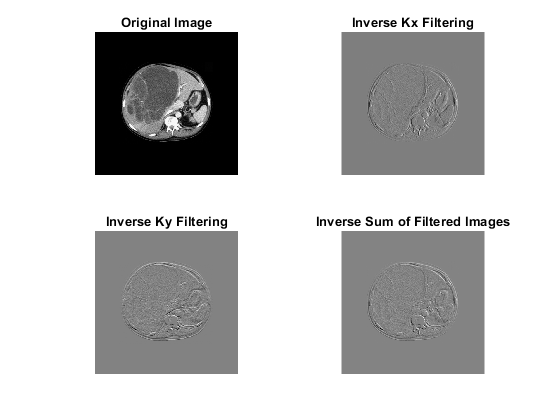

figure; subplot(2,2,1); imshow(ifft2c(X),[]); title('Original Image')
subplot(2,2,2); imshow(ifft2c(X_KX),[]); title('Inverse Kx Filtering')
subplot(2,2,3); imshow(ifft2c(X_KY),[]); title('Inverse Ky Filtering')
subplot(2,2,4); imshow(ifft2c(X_SUM),[]); title('Inverse Sum of Filtered Images')

The images appear to be identical. However, on closer inspection, the actual values in these images have changed slightly. 

clear kx KX kx_pad ky KY ky_pad x X x_sum x_kx X_KX x_ky X_KY X_SUM pads

## **3.2     Spatial Transformations & Landmark Registration**

**In this section you will implement some basic spatial image transformations (translations, rotations, and scalings), and align two images using Landmark registration. In this section you may use any interpolation method you want.**

**(e) Create your own function to translate an image.**

See `translate` below in 'Custom Functions'

**(f) Create your own function to rotate an image.**

See `rotate` below in 'Custom Functions'

**(g) Create your own function to scale an image.**

See `scale` below in 'Custom Functions'

**(h) Load the **`liver.jpeg`** image from the course website. Using your functions from above, rotate it **${40}^{\circ }$**, translate it (30, 20) pixels, and scale it by 1.5. Use **`subplot`** to display the original image **$\mathrm{X}$** and the transformed image **${\mathrm{X}}_T$** at each stage, for all the possible transformation orders. Are they the same?**

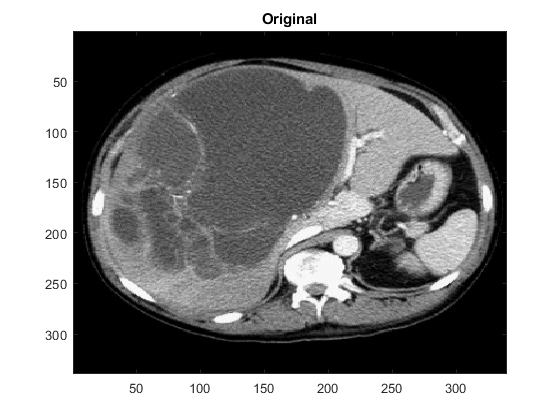

image = imread('liver.jpeg');

% Pad to make array square
if abs(size(image,1)-size(image,2)) 
    if size(image,1)>size(image,2)  % If dim1 is greater than dim2
        pads = ones(size(image,1),(size(image,1)-size(image,2))/2);
        image = [pads image pads];
    else 
        pads = ones((size(image,2)-size(image,1))/2,size(image,2));
        image = [pads; image; pads];
    end
end

figure; imagesc(image); title('Original'); colormap('gray');

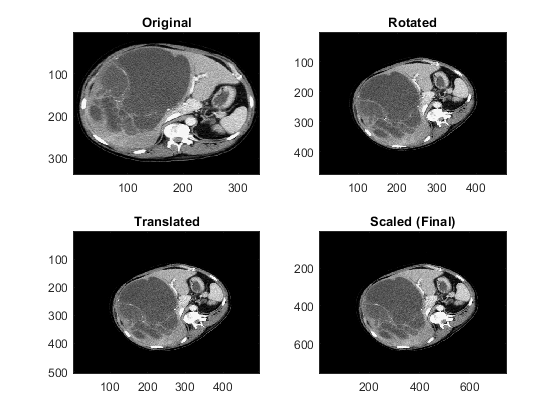


image_rotate = Rotate(image,deg2rad(40));
image_trans = Translate(image_rotate,30,20);
image_scale = Scale(image_trans,1.5);
figure; subplot(2,2,1); imagesc(image); title('Original'); colormap('gray');
subplot(2,2,2); imagesc(image_rotate); title('Rotated'); 
subplot(2,2,3); imagesc(image_trans); title('Translated');
subplot(2,2,4); imagesc(image_scale); title('Scaled (Final)')

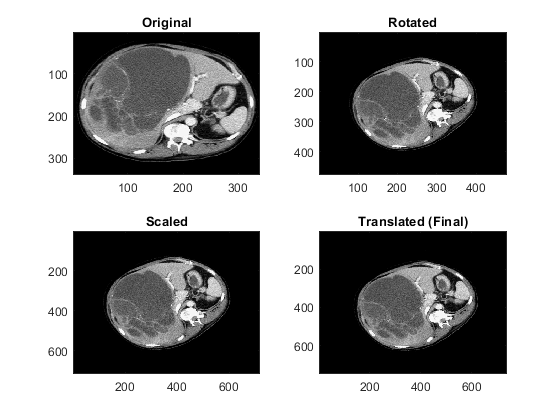


image_rotate = Rotate(image,deg2rad(40));
image_scale = Scale(image_rotate,1.5);
image_trans = Translate(image_scale,30,20);
figure; subplot(2,2,1); imagesc(image); title('Original'); colormap('gray');
subplot(2,2,2); imagesc(image_rotate); title('Rotated'); 
subplot(2,2,3); imagesc(image_scale); title('Scaled');
subplot(2,2,4); imagesc(image_trans); title('Translated (Final)')

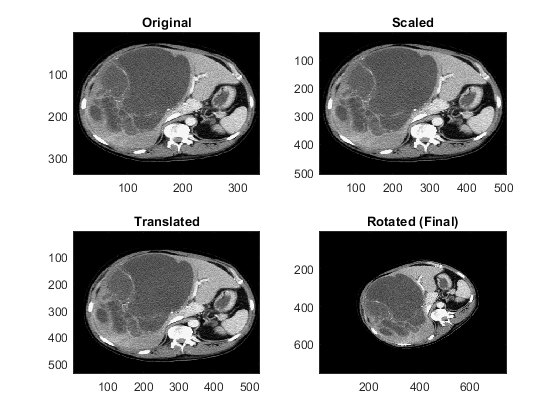


image_scale = Scale(image,1.5);
image_trans = Translate(image_scale,30,20);
image_rotate = Rotate(image_trans,deg2rad(40));
figure; subplot(2,2,1); imagesc(image); title('Original'); colormap('gray');
subplot(2,2,2); imagesc(image_scale); title('Scaled'); 
subplot(2,2,3); imagesc(image_trans); title('Translated');
subplot(2,2,4); imagesc(image_rotate); title('Rotated (Final)')

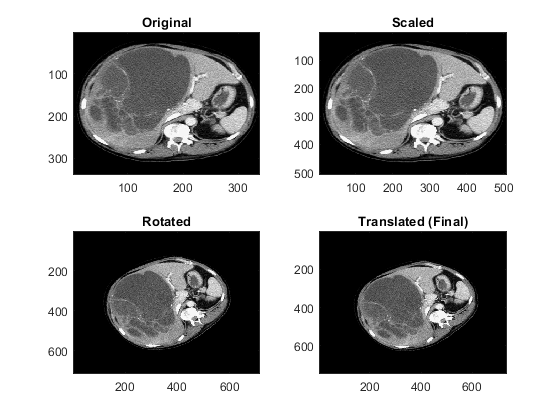


image_scale = Scale(image,1.5);
image_rotate = Rotate(image_scale,deg2rad(40));
image_trans = Translate(image_rotate,30,20);
figure; subplot(2,2,1); imagesc(image); title('Original'); colormap('gray');
subplot(2,2,2); imagesc(image_scale); title('Scaled'); 
subplot(2,2,3); imagesc(image_rotate); title('Rotated');
subplot(2,2,4); imagesc(image_trans); title('Translated (Final)')

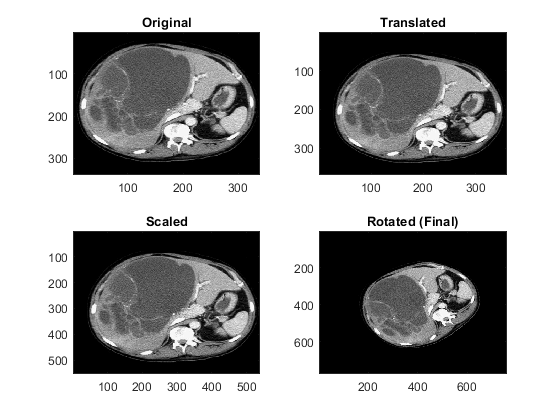


image_trans = Translate(image,30,20);
image_scale = Scale(image_trans,1.5);
image_rotate = Rotate(image_scale,deg2rad(40));
figure; subplot(2,2,1); imagesc(image); title('Original'); colormap('gray');
subplot(2,2,2); imagesc(image_trans); title('Translated'); 
subplot(2,2,3); imagesc(image_scale); title('Scaled');
subplot(2,2,4); imagesc(image_rotate); title('Rotated (Final)')

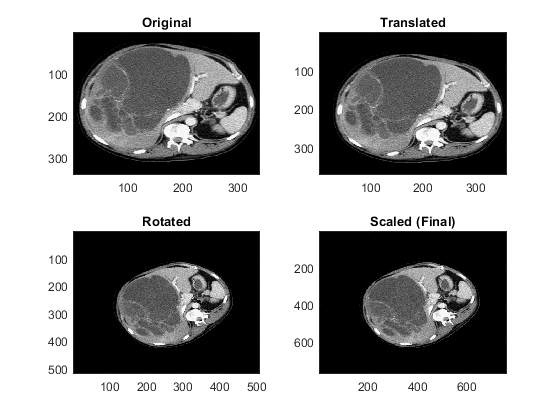

% 
image_trans = Translate(image,30,20);
image_rotate = Rotate(image_trans,deg2rad(40));
image_scale = Scale(image_rotate,1.5);
figure; subplot(2,2,1); imagesc(image); title('Original'); colormap('gray');
subplot(2,2,2); imagesc(image_trans); title('Translated'); 
subplot(2,2,3); imagesc(image_rotate); title('Rotated');
subplot(2,2,4); imagesc(image_scale); title('Scaled (Final)')

While these images do look similar, they are not the same. This can be better seen if we translate the image by a greater amount (e.g. 200 pixels). This intuitively makes sense, as order matters when performing matrix multiplication. 

To demonstrate the similarity to the built-in MATLAB rotate, translate, and scale functions, I will perform a translate, rotate, and scale using MATLAB's imtranslate, imrotate, and imresize on the image and compare that to my functions using a difference image.

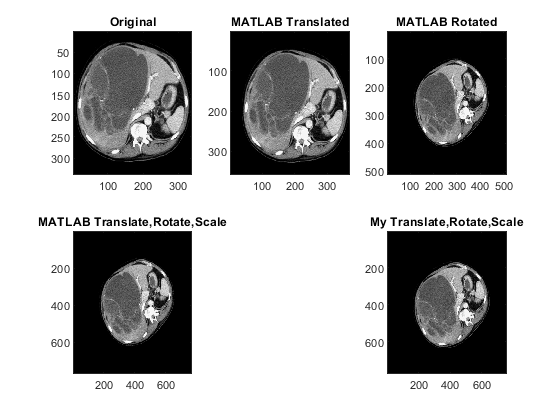

MATLAB_trans = imtranslate(image,[30 20],'OutputView','full');
MATLAB_rotate = imrotate(MATLAB_trans,40);
MATLAB_scale = imresize(MATLAB_rotate,1.5,'nearest');
figure; subplot(2,3,1); imagesc(image); title('Original'); colormap('gray');
subplot(2,3,2); imagesc(MATLAB_trans); title('MATLAB Translated'); 
subplot(2,3,3); imagesc(MATLAB_rotate); title('MATLAB Rotated');
subplot(2,3,4); imagesc(MATLAB_scale); title('MATLAB Translate,Rotate,Scale')
subplot(2,3,6); imagesc(image_scale); title('My Translate,Rotate,Scale')

**(i) To perform Landmark registration, select K = 10 reference points (**$x_k$,$y_k$**) in **$\mathrm{X}$**, and their corresponding points (**${x_k }^{\prime }$,${y_k }^{\prime }$**) in **${\mathrm{X}}_T$** . *****Hint: Determining such points should be easy, as you had control over the spatial transformation*****. Use these points to identify the mapping matrix **$\mathrm{M}$** that aligns **${\mathrm{X}}_T$** with **$\mathrm{X}$**. What do you obtain for **$\mathrm{M}$**?**

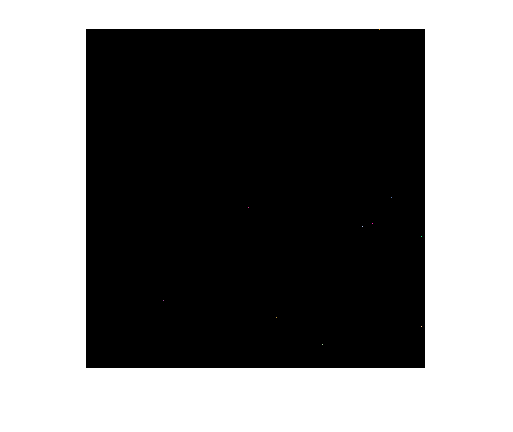

% Set of randomly selected points (using randi())
x = [289   316   198   298     1   208   179   272   169   195;
     191   237   277   336   294   336   163    78   306   287;
     1     1     1     1     1     1     1     1     1     1];

% Set of randomly chosen RGB triplets (to visually distinguish points)
colorRand = [0.7412    0.6667    0.6627    0.9843    0.9294    0.1176    0.8471    0.6314    0.3608    0.9922;
            0.5882    0.8240    0.7294    0.7686    0.5804    0.8627    0.2078    0.3140    0.4710    0.1216;
            0.2471    0.6275    0.8941    0.5804    0.0157    0.4824    0.5529    0.6157    0.6902    0.7039];
   
K = 10;
landmarks = zeros([size(image) 3]); % initialize RGB landmarks image
for i=1:K
    landmarks(x(1,i),x(2,i),:) = colorRand(:,i); % Place color points in landmarks image
end
figure; imshow(landmarks);

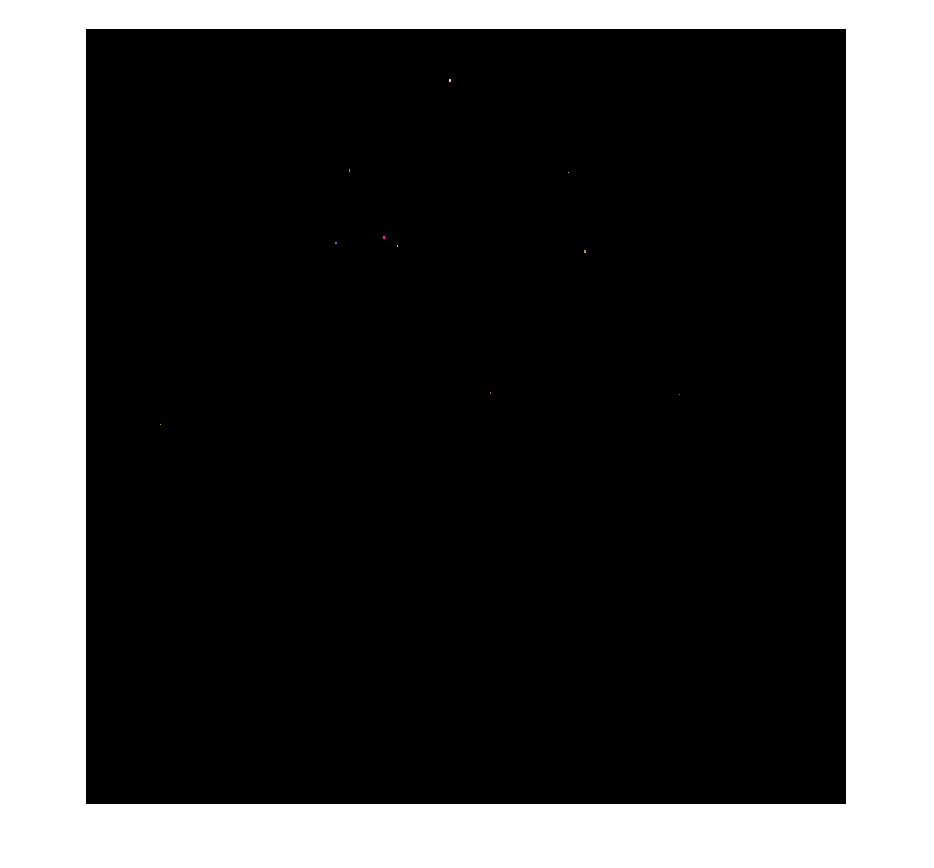

landmarksPrime = Scale(Rotate(Translate(landmarks,30,20),40),1.5); % Translate, Rotate, Scale image
figure; imshow(landmarksPrime);


% Find where the new landmarks exist after transformation
% NOTE: I take the mean of xk' and yk' because the scale functions uses a
% nearest neighbor interpolation. Because of this, one pixel may map to
% multiple pixels in the output image. 
for i=1:K
    [xkp,ykp] = find(landmarksPrime(:,:,1)==colorRand(1,i) & landmarksPrime(:,:,2)==colorRand(2,i)); % find indices of new points
    xp(1,i) = mean(xkp); 
    xp(2,i) = mean(ykp);
    xp(3,i) = 1;
end

M = ((x*x')\(x*xp'))' % Close form solution of least squares Frobenius norm

M =    -1.0012   -1.1177  725.5735
    1.1151   -1.0022  368.6773
    0.0000    0.0000    1.0000


**(j) Create a function that applies a mapping **$\mathrm{M}$** to an image. Use **`subplot`** to display **${\mathrm{X}}_T$** and the result of applying the mapping **$\mathrm{M}$** you obtained above to **${\mathrm{X}}_T$** . Is it the same as **$\mathrm{X}$**?**

T = [1 0 30; 0 1 20; 0 0 1]; % Translate matrix (50x50 pixels to the right)
Sh1 = [1 0 -(340)/2; 0 1 -(340)/2; 0 0 1]; % Shift matrix (rotate about image center)
R = [cos(0.6981) sin(0.6981) 0; -sin(0.6981) cos(0.6981) 0; 0 0 1]; % Rotation matrix (40 degrees clockwise)
Sh2 = [1 0 480.42/2; 0 1 480.42/2; 0 0 1];   % Shift matrix (bring rotation back to center)
S = [1.5 0 0; 0 1.5 0; 0 0 1]; % Scale matrix (scale by 1.5)
M = S*Sh2*R*Sh1*T; % Translate, Rotate, Scale

xp = M*x;
landmarksPrime = zeros([720 720 3]);
for i=1:K
    landmarksPrime(uint16(xp(1,i)),uint16(xp(2,i)),:) = landmarks(x(1,i),x(2,i),:); 
end 

figure; imshow(landmarks);

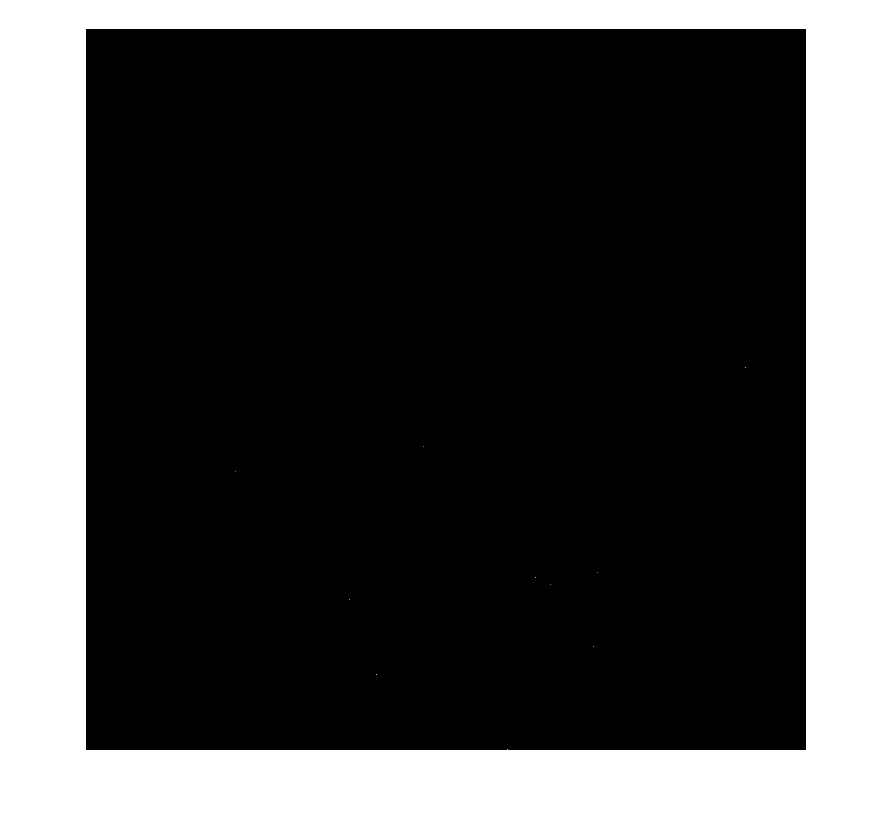

figure; imshow(landmarksPrime);


M10 = ((x*x')\(x*xp'))' % Close form solution of least squares Frobenius norm

M10 =     1.1491    0.9641   54.8196
   -0.9641    1.1491  322.9307
    0.0000    0.0000    1.0000


xp_calculated = M10*x;
landmarksPrime2 = zeros([720 720 3]);
for i=1:K
    landmarksPrime2(uint16(xp_calculated(1,i)),uint16(xp_calculated(2,i)),:) = landmarks(x(1,i),x(2,i),:); 
end 

figure; imshow(landmarksPrime);

figure; imshow(landmarksPrime2); 

l2_error = norm(xp-xp_calculated) % calculate l2 norm of difference vector

l2_error = 1.3868e-12

It is a bit hard to see the points in the figure, however, they are the same. This can be seen when we look at both xp and xp_calculated

xp

xp =   571.0604  646.4367  549.4091  721.2033  339.4274  617.7846  417.6637  442.5774  544.0454  555.6032
  263.7704  290.5969  450.3299  421.7122  659.8012  508.4852  337.6516  150.3129  511.6140  464.7133
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


xp_calculated

xp_calculated =   571.0604  646.4367  549.4091  721.2033  339.4274  617.7846  417.6637  442.5774  544.0454  555.6032
  263.7704  290.5969  450.3299  421.7122  659.8012  508.4852  337.6516  150.3129  511.6140  464.7133
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


**(k) What happens if instead of K = 10 you use K = 5, 3, 2, 1 reference points? What conclusions can you draw from this?**

x5= x(:,1:5); % cut x down to 5
xp5 = xp(:,1:5); % cut x' down to 5 
M5 = ((x5*x5')\(x5*xp5'))' % recalculate M

M5 =     1.1491    0.9641   54.8196
   -0.9641    1.1491  322.9307
    0.0000    0.0000    1.0000


xp_calculated = M5*x; % find transformed points using new M
l2_error = norm(xp-xp_calculated) % l2 error

l2_error = 1.5831e-12


x3 = x(:,1:3);
xp3 = xp(:,1:3);
M3 = ((x3*x3')\(x3*xp3'))' 

M3 =     1.1491    0.9641   54.8196
   -0.9641    1.1491  322.9307
   -0.0000   -0.0000    1.0000


xp_calculated = M3*x;
l2_error = norm(xp-xp_calculated)

l2_error = 1.3894e-11


x2 = x(:,1:2);
xp2 = xp(:,1:2);
M2 = ((x2*x2')\(x2*xp2'))' 

M2 =    -0.4578    1.9073  339.0654
   -0.3814    0.8071  219.8518
         0         0    1.0000


xp_calculated = M2*x;
l2_error = norm(xp-xp_calculated)

l2_error = 843.9316


x1 = x(:,1);
xp1 = xp(:,1);
M1 = ((x1*x1')\(x1*xp1'))' 

M1 = 	1.0e+19 *

   -0.0000    0.0112   -2.1439
   -0.0000    0.0037   -0.7146
         0         0    0.0000


xp_calculated = M1*x;
l2_error = norm(xp-xp_calculated)

l2_error = 3.7071e+19

As expected, the less reference points that are available, the higher the error in the matrix mapping calculation. This is evidenced by the increasing sum of squared errors between the true transformed point locations and the calculated transformed point locations as the number of reference points decrease. However, when using three points, the error is still almost negligible. There is a sharp cutoff in accuracy below 3 points.

### Custom Functions

#### *Corrected Fourier Transform (with shifts)*

function transf = fft2c(x)
    transf = 1/sqrt(length(x(:)))*fftshift(fft2(ifftshift(x)));
end 

#### *Corrected Inverse Fourier Transform (with shifts)*

function transf = ifft2c(x)
    transf = sqrt(length(x(:)))*ifftshift(ifft2(fftshift(x)));
end 

#### *Translate*

function translated = Translate(image,deltaX,deltaY)
    [numRows,numCols,~] = size(image); % Get image dimensions
    T = [1 0 deltaX; 0 1 deltaY; 0 0 1]; % Translation matrix
    for i = 1:numRows
        for j = 1:numCols
            coords = uint16( T*[i;j;1] ); % transform pixel location
            ip = coords(1);
            jp = coords(2);
            translated(ip,jp,:) = image(i,j,:); % put new location in translated image
        end
    end
end

#### *Scale*

function scaled = Scale(image,scale)
    [numRows,numCols,~] = size(image); % Get image dimensions
    rowInds = uint16( (1:(numRows*scale))./scale ); % Create row indices vector and divide by scale
    colInds = uint16( (1:(numCols*scale))./scale ); 
    scaled = image(rowInds,colInds,:); % Get image values for indices
end 

#### *Rotate*

function rotated = Rotate(image,theta)
    [numRows,numCols,~] = size(image); % Get image dimensions
    hx = numRows*sqrt(2); % max hypotenuse
    hy = numCols*sqrt(2);
    Sh1 = [1 0 -hx/2; 0 1 -hy/2; 0 0 1]; % Shift matrix (so we rotated about image center)
    R = [cos(theta) sin(theta) 0; -sin(theta) cos(theta) 0; 0 0 1]; % Rotation matrix
    Sh2 = [1 0 (numRows+1)/2; 0 1 (numCols+1)/2; 0 0 1]; % Shift matrix (overlay new/old coord. systems)
    for i=1:hx
        for j=1:hy
            coords = uint16( Sh2*R*Sh1*[i;j;1] ); % shift, rotate, unshift indices
            ip = coords(1); % primed coordinates (row)
            jp = coords(2); % primed coordinates (column)
            if ip>0 && jp>0 && ip<=numRows && jp<=numCols % if indices are w/in old image
                rotated(i,j,:) = image(ip,jp,:);
            end
        end
    end
end